**Financial Applications**

**Simulating Financial Random Walks for Stock Market Data**

As a data scientist, I often find it fascinating to simulate real-world phenomena using statistical models. In this analysis, I focused on simulating the behavior of stock market portfolios over time using random walks. My goal was to generate a realistic representation of how stock prices might evolve based on daily fluctuations, offering insights into the inherent volatility and randomness of financial markets.

To begin, I generated random daily percentage changes for five stock portfolios over 200 days. These changes were designed to capture both gains and losses, modeled as random values uniformly distributed between −0.5-0.5−0.5 and 0.50.50.5. By using this range, I introduced the variability that reflects real-world market dynamics, albeit in a simplified form. I then calculated the cumulative returns by taking the cumulative sum of these daily changes, effectively simulating the evolution of stock prices over time.

The visualization of this simulation was a critical component of my analysis. I plotted the cumulative returns for each portfolio on a single graph, ensuring clarity and differentiation. To make the results visually appealing and informative, I applied distinct line colors using a pre-defined colormap and adjusted the line thickness for better readability. Additionally, I added axis labels and a descriptive title to provide context, reinforcing the focus on simulated stock market performance.

One of my priorities was to emphasize the variability in portfolio behavior through this plot. The inclusion of a grid made it easier to interpret fluctuations over time, while the cumulative returns on the y-axis underscored the compounding effect of daily percentage changes. 

This simulation exemplified how random walks can be used to model stock price behavior, albeit with the acknowledgment that real markets are influenced by a far more complex set of factors. By leveraging statistical methods to create these simulations, I demonstrated a foundational technique that can be expanded upon for more sophisticated analyses, such as incorporating correlations, external market factors, or machine learning predictions. 

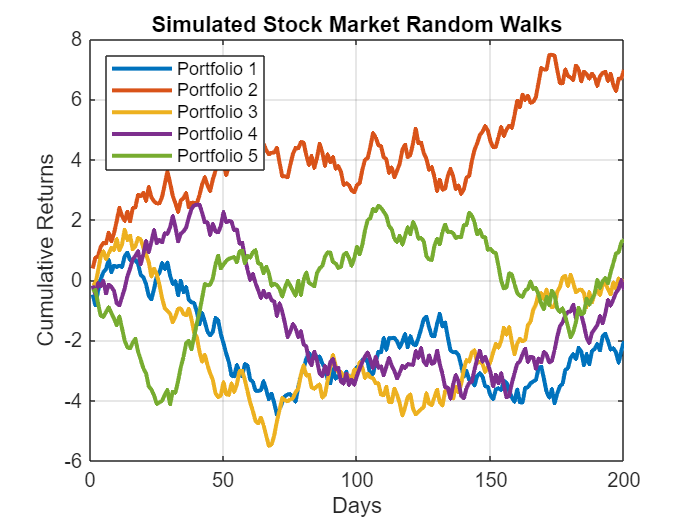

% Simulating Financial Random Walks for Stock Market Data
% I want to simulate the performance of 5 different stock portfolios over 200 days using random walks.

% Generate random daily percentage changes for 5 stock portfolios over 200 days
random_changes = rand(200, 5) - 0.5; % Random values between -0.5 and 0.5 to simulate gains/losses

% Compute cumulative returns to represent the stock market prices
stock_prices = cumsum(random_changes); % Cumulative sum simulates stock price evolution

% Plot the stock prices for each portfolio
figure; % Open a new figure
plot(stock_prices, 'LineWidth', 2); % Plot the data with thicker lines for clarity

% Add a legend to differentiate the stock portfolios
legend({'Portfolio 1', 'Portfolio 2', 'Portfolio 3', 'Portfolio 4', 'Portfolio 5'}, ...
       'Location', 'northwest'); % Place the legend in the top-left corner

% Add a title and labels to the plot for context
title('Simulated Stock Market Random Walks'); % Title describing the simulation
xlabel('Days'); % Label for the x-axis
ylabel('Cumulative Returns'); % Label for the y-axis

% Customize the plot appearance for better differentiation
colormap_lines = lines(5); % Generate distinct colors for the lines
set(gca, 'ColorOrder', colormap_lines, 'NextPlot', 'replacechildren'); % Apply the colors to the lines
grid on; % Add a grid to make the plot easier to read


% Highlight the importance of the simulation
% This plot provides an illustrative example of how stock portfolios might behave with random fluctuations.
